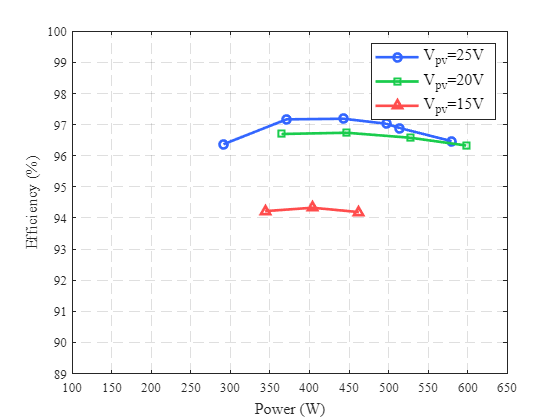

% 定义光伏端口的功率和效率数据
% 对应25V的光伏端口数据
power_25V = [579.756, 514.424, 496.956, 443.251, 370.932,291.19];
efficiency_25V = [96.47, 96.89, 97.03, 97.19, 97.17,96.37];

% 对应20V的光伏端口数据
power_20V = [598.216, 527.41, 446.833, 364.668];
efficiency_20V = [96.33, 96.58, 96.74, 96.7];

% 对应15V的光伏端口数据
power_15V = [462.454, 403.854, 343.895];
efficiency_15V = [94.19, 94.33, 94.22];

% 正向数据（电池端口到DC bus）
power_forward = [623.5, 585.4, 527, 509, 398.795, 361.7];
efficiency_forward = [96.509, 96.714, 96.933, 97.074, 97.516, 97.470];

% 创建一个新的图形窗口
figure;

% 绘制25V光伏端口数据
plot(power_25V, efficiency_25V, '-o', 'DisplayName', 'V_{pv}=25V', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [0.2, 0.4, 1]); % 使用更柔和的蓝色

hold on;

% 绘制20V光伏端口数据
plot(power_20V, efficiency_20V, '-s', 'DisplayName', 'V_{pv}=20V', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [0.1, 0.8, 0.3]); % 使用更柔和的绿色

% 绘制15V光伏端口数据
plot(power_15V, efficiency_15V, '-^', 'DisplayName', 'V_{pv}=15V', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [1, 0.3, 0.3]); % 使用更柔和的红色

% 设置坐标轴标签
xlabel('Power (W)', 'FontSize', 12, 'FontName', 'Times New Roman');
ylabel('Efficiency (%)', 'FontSize', 12, 'FontName', 'Times New Roman');


% 设置坐标轴范围
xlim([100, 650]); % 将横坐标范围从300开始
ylim([89, 100]); % 根据效率范围，设定纵坐标范围

% 添加网格
grid on;
set(gca, 'GridLineStyle', '--'); % 设置网格线为虚线

% 添加图例
legend('Location', 'northeast', 'FontSize', 12, 'FontName', 'Times New Roman');

% 设置字体为新罗马字体
set(gca, 'FontName', 'Times New Roman');

% 显示图形
hold off;